# Pressure Drops in Circuit

Sun Devil Rocketry 2021 Brian Terasaki 9/18/21

Code sources: 

Patrick Imper 4/1/20 - deltaPCurcuit.mlx

clc; clear all; close all; format compact;


There will be five locations on the LOx side:

Location 1:

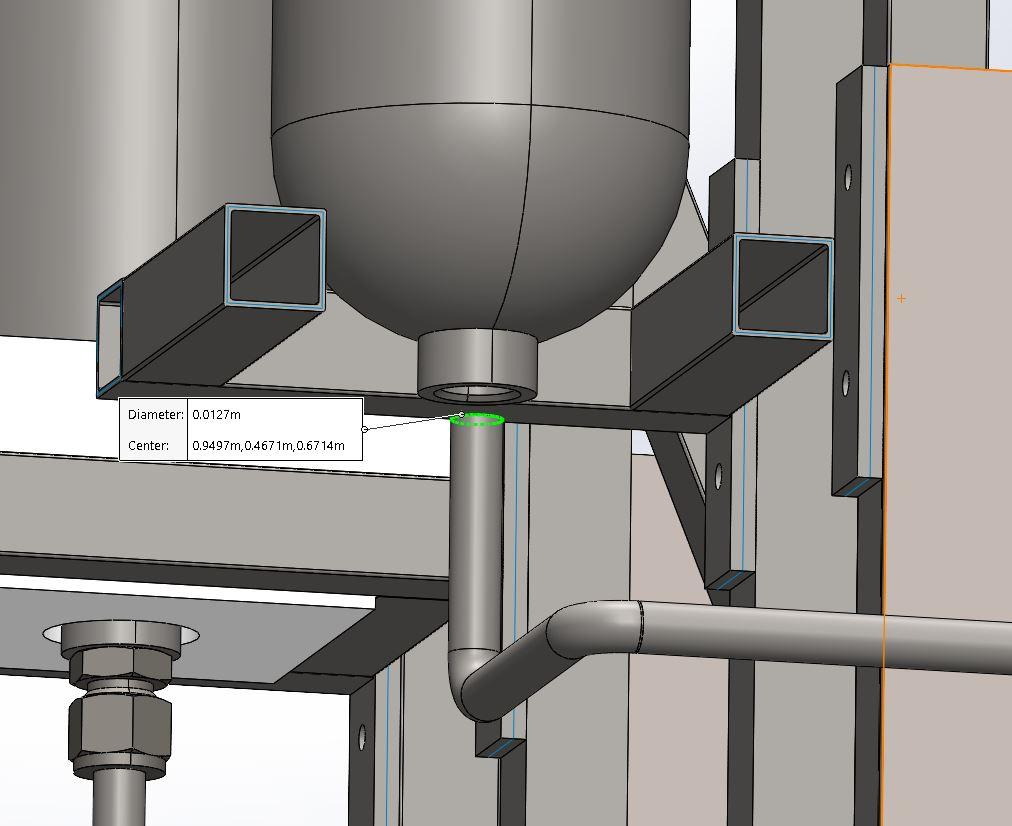

Location 2:

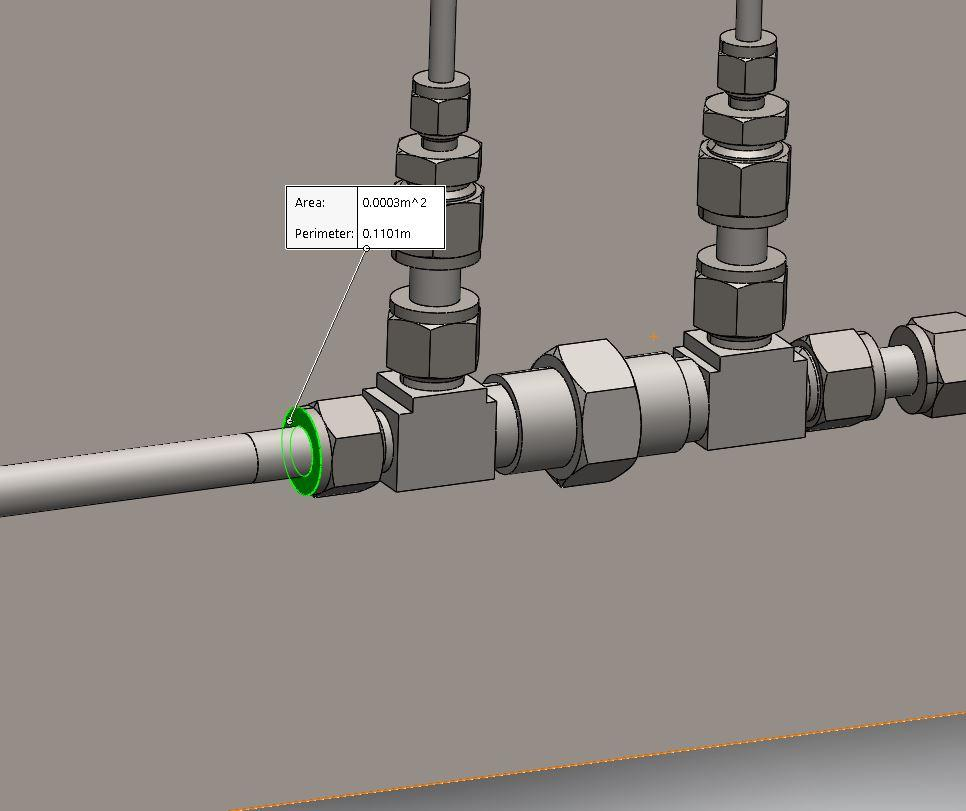

Location 3:

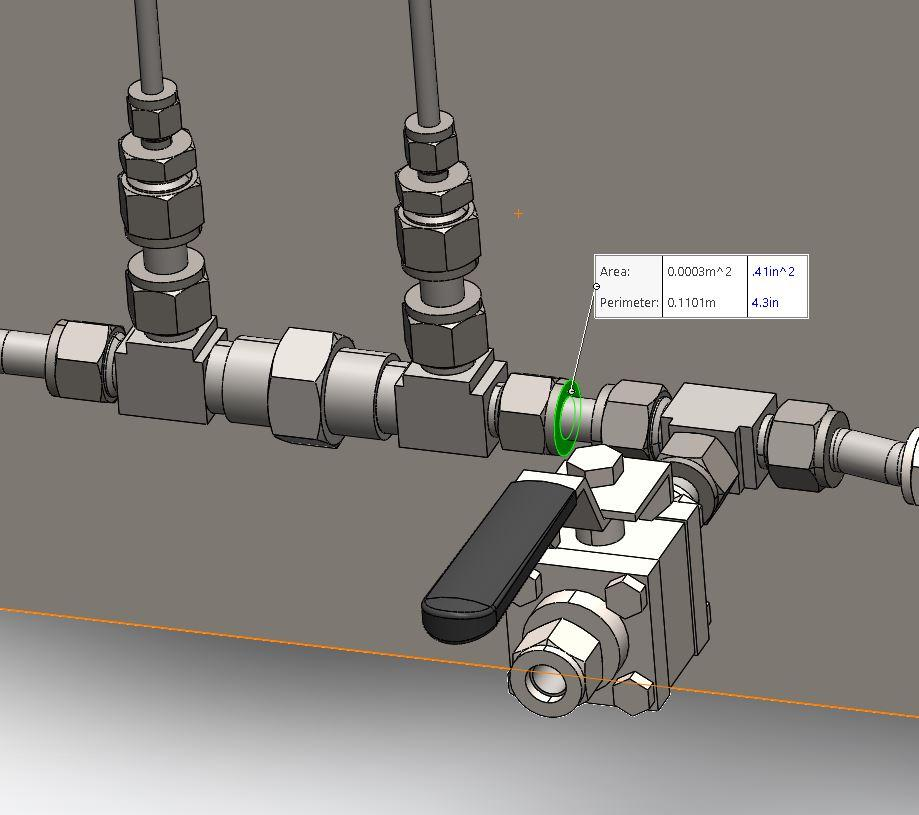

## LOX Side:

## Sum of Differences in Heights, and Sum of Length of Plumbing

L = 1.405 % Length of plumbing

L = 1.4050

x = linspace(0,L,100);

for i = 1:length(x)

% At Location 1:
if x(i) < 0.3312982267
   sumH_LOx = 0; % Sum of the changes in height for LOx (meters)
   suml_LOx = 0; % Sum in the length of plumbing for LOx (meters)
% At Location 2:
elseif x(i) < 0.4892982267
   sumH_LOx = 0.0577;
   suml_LOx = 111;
% At Location 3:
elseif x(i) < 0.5992982267
    
% At Location 4:
elseif x(i) < 0.9674982267
    
% At Location 5:
elseif x(i) < 1.404913256
    
% At End
else 
    
end

Index exceeds the number of array elements (1).

## Fittings in our Plumbing Circuit

LOx side

% At Location 1:
if x(i) < 0.3312982267
    o_couplings = 0; % Number of compression fitting couplings (2 per teethrough usually)
    o_90s = 0; % Number of 90 degree bends (R/D > 1)
    o_teethrough = 0; % Number of tee-through fittings (does not account for tube couplings)
% At Location 2:
elseif x(i) < 0.4892982267
    o_couplings = 0;
    o_90s = 2;
    o_teethrough = 0;
% At Location 3:
elseif x(i) < 0.5992982267
    o_couplings = 4;
    o_90s = 2;
    o_teethrough = 2;
% At Location 4:
elseif x(i) < 0.9674982267
    o_couplings = 7;
    o_90s = 2;
    o_teethrough = 3;
% At Location 5:
elseif x(i) < 1.404913256
    o_couplings = 10;
    o_90s = 2;
    o_teethrough = 4;
% At End
else 
    o_couplings = 11;
    o_90s = 2;
    o_teethrough = 4;
end

% Kerosene Side
% k_couplings = 11; % Number of compression fitting couplings
% k_90s = 2; % Number of 90 degree bends (R/D > 1)
% k_teethrough = 4; % Number of tee-through fittings (does not account for tube couplings)

## Constant/Determined

g = 9.80665; % Gravitatinal acceleration (m/s^2)

odImp = 0.5; % Stainless tubing outer diameter (inches)
wallThicc = 0.035; % Tubing wall thickness (inches)

idImp = odImp-(2*wallThicc); % Stainless tubing inner Diameter (inches)

o_mfr = 1.0556; % Mass flow rate oxidizer (lbm/s)
k_mfr = 1.2599; % Mass flow rate kerosene + Film Cooling) (lbm/s) 

oDen = 1140; % LOX density @ ~ -200 degrees C (kg/m^3)
kDen = 810; % Kerosene density @ 20 degrees C (kg/m^3)

o_mu = 6.95*10^(-6); % Dynamic viscosity of LOX @ -183 degrees C (N*s/m^2 or Pa*s)
k_mu = .192 *10^(-3); % Dynamic viscosity of kerosene @ 20 degrees C (Ns/m^2 or Pa*s)

o_SG = 1.143; % LOx specific gravity (Unitless)
k_SG = 0.810; % Kerosene specific gravity (Unitless)

cv_check = 1.68; % Coefficient Volume for chosen Check Valve (Unknown?)
cv_valve = 7.5; % Coefficient Volume for chosen Main Valves (Unknown?)

orifice_drop = 30; % Designed optimal orifice pressure drop (PSI)
cc_pressure = 250; % Chamber pressure (psig)
injector_drop = 50; % Injector pressure drop (PSI)
cooling_drop = 0; % Regenetive cooling drop (PSI)

ssr = 0.002; % Stainless steel roughness (mm)

## Basic Calculations/Converting Units

idMet = idImp/39.3700787; % Stainess tubing inner diameter (meters)

o_mfrMET = o_mfr*0.45359237; % Mass flow rate oxidizer (kg/s)
k_mfrMET = k_mfr*0.45359237; % Mass flow rate fuel (kg/s)

o_vfr = o_mfrMET/oDen*15850.323141; % volumetric flow rate oxidizer (GPM)
k_vfr = k_mfrMET/kDen*15850.323141; % volumetric FLow Rate fuel (GPM)

ssrr = ssr/(idMet*1000); % Stainless Steel Relative Roughness (Roughness/Diameter) (Unitless)

A = pi*(idMet/2)^2; % Tubing area (meters^2)

vo = o_mfrMET/(oDen * A); % Velocity of LOX in tubing (m/s)
vk = k_mfrMET/(kDen * A); % Velocity of Kerosene in tubing (m/s)

o_Reyn = (oDen*vo*idMet)/o_mu; % Reynolds # for LOX (Unitless)
k_Reyn = (kDen*vk*idMet)/k_mu; % Reynolds # for Kerosene (Unitless)

## Moody Chart Calculations (To Get Friction Factor)

C = ssrr/3.7;
B = 2.51/o_Reyn;
x = -1.8*log10((6.9/o_Reyn)+C^1.11);
for v=1:1:3
    y = x+2*log10(C+B*x);
    y2= 1+2*(B/log(10))/(C+B*x);
    x = x - y/y2;
end
ff_o = 1/(x^2); % Friction Factor for LOX (Unitless)

## Calculating K Values for Fittings and Valves using 2K Method

% The diameter used in this is imperial for a reason, it's required for this method

sumK_LOx = 0.04*o_couplings + ((200/o_Reyn)+0.1*(1+(1/idImp)))*o_teethrough + ((800/o_Reyn)+0.2*(1+(1/idImp)))*o_90s;
% sumK_K = 0.04*k_couplings + ((200/k_Reyn)+0.1*(1+(1/idImp)))*k_teethrough + ((800/k_Reyn)+0.2*(1+(1/idImp)))*k_90s;

## Head Loss Constants

HmajLOx_const = (ff_o*vo^2)/(2*g*idMet); % Head loss major constant LOx (Unitless)
HminLOx_const = (vo^2)/(2*g); % Head loss minor constant LOx (meters)

% HmajK_const = (ff_k*vk^2)/(2*g*idMet); % Head loss constant Kerosene (Unitless)
% HminK_const = (vk^2)/(2*g); % Head loss minor constant Kerosene (meters)

## Calculating Pressure Loss

% At Location 1:
if i == 1
    deltaP_Lox(i) = (oDen*g)/6894.76*(sumH_LOx+(HmajLOx_const*suml_LOx) + (HminLOx_const*sumK_LOx)); % Pressure loss for LOx (PSI)
% At Location 2:
elseif i == 2
    deltaP_Lox(i) = (oDen*g)/6894.76*(sumH_LOx+(HmajLOx_const*suml_LOx) + (HminLOx_const*sumK_LOx));
% At Location 3:
elseif i == 3
    deltaP_Lox(i) = orifice_drop + (oDen*g)/6894.76*(sumH_LOx+(HmajLOx_const*suml_LOx) + (HminLOx_const*sumK_LOx));
% At Location 4:
elseif i == 4
    deltaP_Lox(i) = o_vfr^2*o_SG*(1/cv_check^2+1/cv_valve^2) + orifice_drop + (oDen*g)/6894.76*(sumH_LOx+(HmajLOx_const*suml_LOx) + (HminLOx_const*sumK_LOx));
% At Location 5:
else
    deltaP_Lox(i) = o_vfr^2*o_SG*(1/cv_check^2+1/cv_valve^2) + orifice_drop + (oDen*g)/6894.76*(sumH_LOx+(HmajLOx_const*suml_LOx) + (HminLOx_const*sumK_LOx));
end
end

## Kerosene Side

## Fittings in our Plumbing Circuit

% Kerosene Side
% k_couplings = 11; % Number of compression fitting couplings
% k_90s = 2; % Number of 90 degree bends (R/D > 1)
% k_teethrough = 4; % Number of tee-through fittings (does not account for tube couplings)

## Sum of Differences in Heights, and Sum of Length of Plumbing

% sumH_K = 0.0924152076; % Sum of the changes in height for Kerosene (meters)
% suml_K = 1.5; % Sum in the length of plumbing for Kerosene (meters)

## Moody Chart Calculations (To Get Friction Factor)

C = ssrr/3.7;
B = 2.51/k_Reyn;
x = -1.8*log10((6.9/k_Reyn)+C^1.11);
for v=1:1:3
    y = x+2*log10(C+B*x);
    y2= 1+2*(B/log(10))/(C+B*x);
    x = x - y/y2;
end
ff_k = 1/(x^2); % Friction Factor for Kerosene (Unitless)

## Calculating K Values for Fittings and Valves using 2K Method

% The diameter used in this is imperial for a reason, it's required for this method

% sumK_K = 0.04*k_couplings + ((200/k_Reyn)+0.1*(1+(1/idImp)))*k_teethrough + ((800/k_Reyn)+0.2*(1+(1/idImp)))*k_90s;

## Head Loss Constants

% HmajK_const = (ff_k*vk^2)/(2*g*idMet); % Head loss constant Kerosene (Unitless)
% HminK_const = (vk^2)/(2*g); % Head loss minor constant Kerosene (meters)